## SPACE MISSION ANALYSIS AND DESIGN 

## AY 2020 / 2021

## MORPHEUS 

### Authors:

### Bassissi Enrico

### Morgese Marco

# Setup for default options

set(0, 'DefaultTextFontSize', 22)
set(0, 'DefaultAxesFontSize', 22)
set(0, 'DefaultLegendFontSize', 22)
set(0, 'DefaultAxesXGrid', 'on')
set(0, 'DefaultAxesYGrid', 'on')
set(0, 'DefaultLegendInterpreter', 'latex')
set(0, 'DefaultAxesTickLabelInterpreter', 'latex')
set(0, 'DefaultTextInterpreter', 'latex')
set(0, 'DefaultLineLineWidth', 2)
format short

# Initializing the Environment

clear all; close all; clc;
addpath time
addpath Figures
addpath Figures\Orbits
addpath Functions
AU = astroConstants(2);
muSun = astroConstants(4);

% colors = [0         0.4470    0.7410;...
%           0.8500    0.3250    0.0980;...
%           0.9290    0.6940    0.1250;...
%           0.4940    0.1840    0.5560;...
%           0.4660    0.6740    0.1880;...
%           0.3010    0.7450    0.9330;...
%           0.6350    0.0780    0.1840;...
%           0.7       0         0];

% Palette ESA
colors = [0    50   71;... % DEEP SPACE
          207  29   57;... % EXCITE RED +1
          0    142  122;... % PURE TEAL +1
          251  171  24;... % ENLIGHT YELLOW
          244  121  32;... % ENLIGHT YELLOW +1
          150  1    54;... % EXCITE RED +2
          167  85   52;... % ENLIGHT YELLOW +2
          0    97   158;... % TRUSTY AZURE +1
          30   51   120;... % TRUSTY AZURE +2
          0    103  98;... % PURE TEAL +2
          51   94   111;... % DEEP SPACE -1
          0    0    0]./255; % BLACK

# Module Extraction From Python Library

#### Import the *neo_api* py library

module = py.importlib.import_module('neo_api_function');

#### Reload the library in case of some changing in the python code while working in Matlab

module = py.importlib.reload(module);

# Risk List Definition

#### Obtain the *Sentry* risk list

sentry_risk_names=py.neo_api_function.get_sentry_risk_list();

#### Obtain the ***NEOCC***** esa risk list** (.txt required, can be download by TODO add link)

esa_risk_names=py.neo_api_function.extract_esa_name_from_file("esa_risk_list.txt");

#### Merge risk list

py_risk_list=py.neo_api_function.merge_risk_lists(esa_risk_names, sentry_risk_names);

#### Query ***JPL SBDB*** for the bodies in the risk list

py_dict_risk_list=py.neo_api_function.get_dict(py_risk_list);

29075 could raise error in importing virtual impact data


# Explore DB

#### MOID vs Magnitude

py_MOID_H=py.neo_api_function.MOID_H(py_dict_risk_list)

2010MY112 does not have magnitude info
2010MZ112 does not have magnitude info
2010MA113 does not have magnitude info


py_MOID_H =   Python tuple with no properties.

    ([0.023863, 0.000342446, 0.00484466, 0.0027088, 0.00299328, 0.000465933, 0.00138299, 0.012335, 0.00125091, 0.00105179, 0.00843783, 0.0217991, 0.00131586, 0.00199014, 0.000902841, 0.00222756, 0.000386873, 0.0374655, 0.00516786, 0.000990511, 0.00330311, 0.00259932, 0.00100642, 0.00286821, 0.011159, 0.00266016, 0.00360636, 0.000501304, 0.00204344, 0.00212611, 0.00591383, 0.0100471, 0.000852474, 0.000436354, 0.000224438, 0.00992183, 0.00263847, 0.0164127, 0.0118918, 0.0015896, 0.00113629, 0.00248243, 0.00571679, 0.0294783, 0.00111357, 0.000973277, 0.000744929, 0.00350668, 0.000365051, 0.00199274, 0.000499886, 0.00373875, 0.0013683, 0.0194417, 0.0017792, 0.00137024, 0.020536, 0.00188783, 0.00137649, 0.000788756, 0.00810998, 0.00138675, 0.00124506, 0.00432215, 0.00920047, 0.000939949, 0.201873, 0.0697112, 0.00294161, 0.00100413, 0.029942, 0.00174338, 0.000129424, 0.0013209, 0.

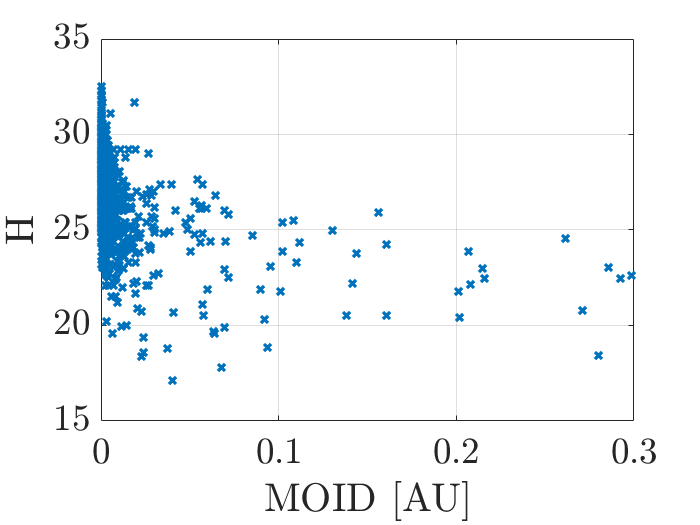

MOID = cellfun(@double,cell(py_MOID_H{1}));
H = cellfun(@double,cell(py_MOID_H{2}));
plot(MOID,H, 'x');
xlabel('MOID [AU]')
ylabel('H')

#### Magnitude vs Orbit Condition Code

py_H_OCC=py.neo_api_function.H_OCC(py_dict_risk_list);

2010MY112 does not have magnitude info
2010MZ112 does not have magnitude info
2010MA113 does not have magnitude info


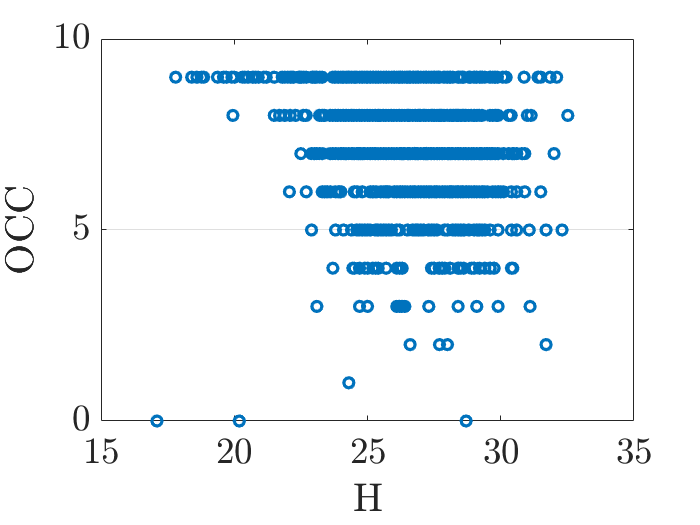

H = cellfun(@double,cell(py_H_OCC{1}));
OCC = cellfun(@double,cell(py_H_OCC{2}));
plot(H,OCC,'o');
set(gca,'XGrid','off','YGrid','on')
xlabel('H')
ylabel('OCC')

#### Obtain Table with all Asteroids and Chosen Characteristics

py_physical_properties = module.get_df_for_sbdb_visualization(py_dict_risk_list);

2010MY112 does not have magnitude info
2010MZ112 does not have magnitude info
2010MA113 does not have magnitude info


physical_properties = double(py_physical_properties{1}.values);
separate_stuff = strsplit(char(py_physical_properties{2}),{']','['});
physical_properties_names = cellfun(@string,strsplit(separate_stuff{2},',','CollapseDelimiters',true));

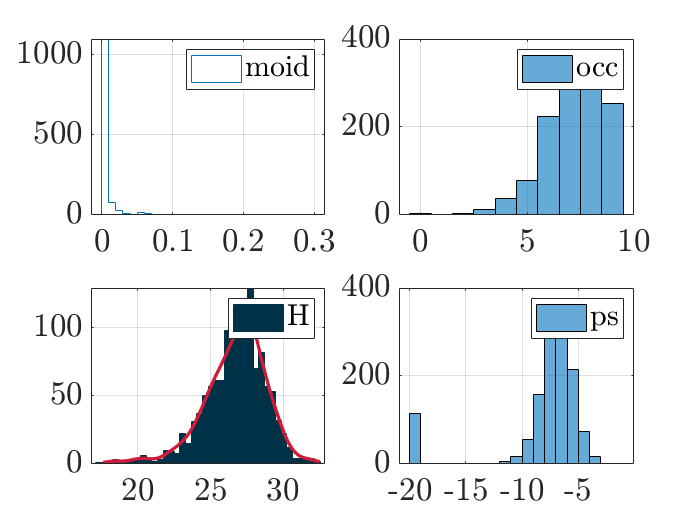

figure()
title('PHAs Characteristics Distribution')
subplot(2,2,1)
histogram(physical_properties(:,1),'DisplayStyle','stairs');
legend('moid')
subplot(2,2,2)
histogram(physical_properties(:,2),'FaceAlpha',0.6);
legend('occ')
subplot(2,2,3)
h3=histfit(physical_properties(:,3),40,'kernel'); % weibull
h3(1).FaceColor=colors(1,:);
h3(1).EdgeColor=colors(1,:);
h3(2).Color=colors(2,:);
legend('H')
subplot(2,2,4)
histogram(physical_properties(:,4));
legend('ps')

# Selection of the Asteroids and Their Properties

#### Dictionary extraction of the filtered list

py_selected_asteroids = py.neo_api_function.refined_selection(py_dict_risk_list);

2012QD8
Max Palermo Scale:-3.88
OCC:7
2005WG57
Max Palermo Scale:-5.46
OCC:7
2012BY1
Max Palermo Scale:-5.56
OCC:8
2012SY49
Max Palermo Scale:-6.13
OCC:7
2008XU2
Max Palermo Scale:-6.23
OCC:7
2008KN11
Max Palermo Scale:-6.26
OCC:7
2020UE
Max Palermo Scale:-6.34
OCC:6
2006HX57
Max Palermo Scale:-6.82
OCC:7
2006SC
Max Palermo Scale:-6.89
OCC:6


#### Properties dictionary and name list

py_selected_asteroids_dict = py_selected_asteroids{1};
selected_asteroids_names = cellfun(@string,cell(py_selected_asteroids{2}));

# Selected Asteroids Characteristics Cell

[selected_asteroids_orbital_elements_and_sigma, orbital_elements_units] = ...
    get_orbital_elements_and_sigma(selected_asteroids_names,py_selected_asteroids_dict);

incl_asteroids = zeros(length(selected_asteroids_orbital_elements_and_sigma),1);
for i = 1:length(selected_asteroids_orbital_elements_and_sigma)
    incl_asteroids(i) = selected_asteroids_orbital_elements_and_sigma{i}(3,1);
end
clearvars i

table(selected_asteroids_names',incl_asteroids)

ans = 9×2 table
       Var1       incl_asteroids
    __________    ______________

    "2012BY1"        0.47648    
    "2008KN11"        5.2718    
    "2006SC"          10.427    
    "2006HX57"       0.19698    
    "2012SY49"        1.1942    
    "2012QD8"         5.5805    
    "2020UE"          3.3694    
    "2005WG57"       0.42653    
    "2008XU2"         2.9533    


# Synodic Periods

syn_periods = zeros(length(selected_asteroids_names),length(selected_asteroids_names));
for i = 1:length(selected_asteroids_names) % rows
    for j = 1:length(selected_asteroids_names) % cols
        if i>j
            syn_periods(i,j) = synodic_period(selected_asteroids_orbital_elements_and_sigma{i}(1)*AU,...
                selected_asteroids_orbital_elements_and_sigma{j}(1)*AU)/(3600*24); % days
        else
            syn_periods(i,j) = NaN;
        end
    end
end
clearvars i j

# Preliminary Mission Analysis

#### Find mission for given asteroid

req_mjd0 = 59215; % from 2021
req_duration = 365*7; % to 2028
req_min_tof = 100;
req_max_tof = 365*10;
req_step_size = 10;
missions_dict=py.neo_api_function.bi_impulsive_mission(py.str("2006HX57"),py.int(req_mjd0), py.int(req_duration),py.int(req_min_tof),py.int(req_max_tof),py.int(req_step_size)); 

Error using neo_api_function>get_mission_profiles (line 56)
Python Error: KeyError: 'selectedMissions'

Error in neo_api_function>bi_impulsive_mission (

%% TODO
%{
name=[];
    for i=1:int(py.len(refined_selected_name))
        
        cname=cell(missions_dict{refined_selected_name{i}})
        name(i)=cellfun(@string, cname)
    end
%}


% TODO
missions_dict{refined_selected_name{1}}.keys()
py_pc_dv = missions_dict{refined_selected_name{1}}{'porkchop_dv'};
pc_dv = double(py_pc_dv);
py_dep_date = missions_dict{refined_selected_name{1}}{'dep_date'};
dep_date_mjd = cellfun(@double, cell(py_dep_date));
dep_date = zeros(length(dep_date_mjd),6);
dep_date_str = cell(length(dep_date_mjd),1);
for i=1:length(dep_date_mjd)
    dep_date(i,:) = mjd2date(dep_date_mjd(i));
    dep_date_str{i} = string(dep_date(i,3))+" "+string(dep_date(i,2))+" "+string(dep_date(i,1));
end


tof = cellfun(@double, cell(missions_dict{refined_selected_name{1}}{'tof'}));

contour(dep_date_mjd,tof,pc_dv)
colorbar

# Orbit Characterisation

#### Call to NASA JPL Horizons

% Earth 1 year ephemerides
epoch_start = '2021-01-01';
epoch_stop = '2022-01-01';
step = '5d';
type_elements = 'Vectors';

py_data_Earth = py.neo_api_function.get_earth_ephemerides(py.str(epoch_start),...
                py.str(epoch_stop),py.str(step),py.str(type_elements));
data_Earth = double(py_data_Earth);

% Asteroids
PointOfView = 'Sun';
epoch_start = '2021-01-01';
epoch_stop = '2026-01-01';
step = '5d';
type_elements = 'Vectors';

horizons_data = cell(length(selected_asteroids_names),1);
for name = 1:length(selected_asteroids_names)
    % data extraction section
    py_data = py.neo_api_function.get_horizons_ephemerides(py.str(selected_asteroids_names(name)),py.str(PointOfView),...
                      py.str(epoch_start),py.str(epoch_stop),py.str(step),py.str(type_elements));
    horizons_data{name} = double(py_data);
    
    % plotting section
    h_fig = figure();
    h_EA = plot3(data_Earth(:,1),data_Earth(:,2),data_Earth(:,3),...
           'LineWidth',2.2,"Color",colors(1,:));
    hold on
    h_asteroid = plot3(horizons_data{name}(:,1),horizons_data{name}(:,2),horizons_data{name}(:,3),...
                 'LineWidth',2.2,"Color",colors(2,:));
    axis equal; grid on;
    xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
    legend([h_EA, h_asteroid],'Earth',selected_asteroids_names(name),'Location',"northeast");
    saveas(h_fig,sprintf('./Figures/Orbits/orb%d.png',name));
    %print(h_fig,sprintf('./Figures/Orbits/orb%d.pdf',name),'-dpdf','-bestfit'); 
    %exportgraphics(gca,sprintf('./Figures/Orbits/orb%d.png',name),'ContentType','image');
end
